# Indoor MIMO-OFDM Communication Link using Ray Tracing

This example shows how to perform ray tracing in an indoor environment and use the results to build a channel model for a link level simulation with the MIMO-OFDM technique. 

## Introduction

Ray tracing [1] has become a popular technique for radio frequency (RF) analysis, site planning, channel modelling, and link level analysis due to the trend for modern communications systems to operate at RF frequencies in the tens of GHz range. Unlike stochastic models, the ray tracing method is 3-D environment and transceiver sites specific and can have high sensitivity in the surrounding environment. Without a simple formula to calculate distance-based path losses, the ray tracing method relies on numeric simulations, and is typically less costly than field measurements. Results from ray tracing can be used to build multipath channel models for communication systems. For example, a ray tracing based channel model has been specified in Section 8 of TR 38.901 [2] for 5G and in IEEE 802.11ay for WLAN [3]. 

This example starts with ray tracing analysis between one transmitter site and one receiver site in a 3-D conference room. Computed rays are used to construct a deterministic channel model which is specific for the two sites. The channel model is used in the simulation of a MIMO-OFDM communication link. This diagram characterizes the communication link. 

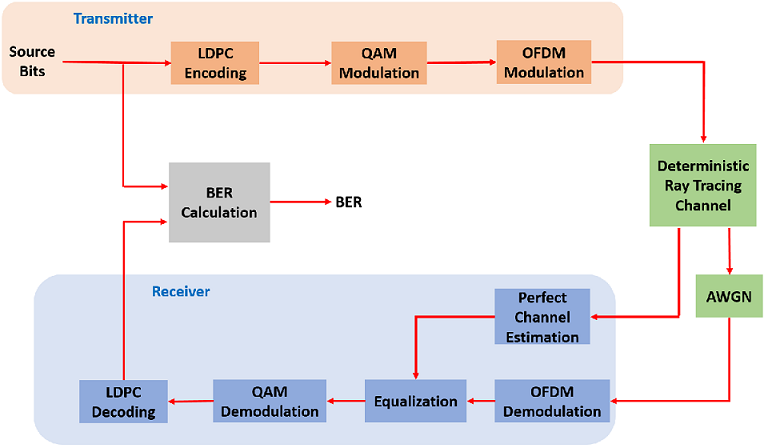

The ray tracing is performed in an indoor environment. The same ray tracing methods can be applied to build channel models for indoor or outdoor environments. For ray tracing analysis in an outdoor urban setting, refer to the [Urban Channel Link Analysis and Visualization using Ray Tracing](docid:comm_ug#mw_bbe699d8-fa2e-4a96-b089-bfcbb2073d28) example. 

## 3-D Indoor Scenario

Specify the indoor 3-D map in STL format for a small conference room with one table and four chairs. The STL format is one of the most common 3-D map formats and can often be converted from other 3-D map formats in a variety of 3-D software. 

clear;
clc;
close all;
%mapFileName = "R1_cubeoid.stl";
mapFileName = "many_sub_smoothed_v2_hole.stl"

mapFileName = "many_sub_smoothed_v2_hole.stl"

Define carrier frequency at 5.8 GHz and calculate wavelength

fc = 5.8e9;
lambda = physconst("lightspeed")/fc;

The transmit antenna is a 4-element uniform linear array (ULA) which has twice of the wavelength between the elements. The receive antenna is a 4x4 uniform rectangular array (URA) which has one wavelength between the elements. Both antennas are specified by an [arrayConfig](docid:comm_ref#mw_dbb0a5cb-6891-4dda-ac8f-b3381779bc58) object.

txArray = arrayConfig("Size",[4 1],"ElementSpacing",2*lambda);
rxArray = arrayConfig("Size",[4 1],"ElementSpacing",2*lambda);

Use the [helperViewArray](matlab:openExample('comm/IndoorCommLinkUsingRayTracingExample','supportingFile','helperViewArray.m')) function to visualize the ULA and URA geometries where antenna elements are numbered for input/output streams. 

helperViewArray(txArray);

'helperViewArray' is used in Indoor MIMO-OFDM Communication Link Using Ray Tracing.

helperViewArray(rxArray);

Specify a transmitter site close to the upper corner of the room, which can be a Wi-Fi access point. Specify a receiver site slightly above the table and in front of a chair to represent a laptop or mobile device. 

tx = txsite("cartesian", ...
    "Antenna",txArray, ...
    "AntennaPosition",[-25; 10; 1], ...
    'TransmitterFrequency',5.8e9);

rx = rxsite("cartesian", ...
    "Antenna",rxArray, ...
    "AntennaPosition",[12; -20; 5], ...
    "AntennaAngle",[0;45]);

Use the `siteviewer` function with the map file specified to view the scene in 3-D in Site Viewer. Use the `show` function to visualize the transmitters and receivers.

siteviewer("SceneModel",mapFileName);
show(tx,"ShowAntennaHeight",false)
show(rx,"ShowAntennaHeight",false)

Pan by left-clicking, zoom by right-clicking or by using the scroll wheel, and rotate the visualization by clicking the middle button and dragging or by pressing Ctrl and left-clicking and dragging.

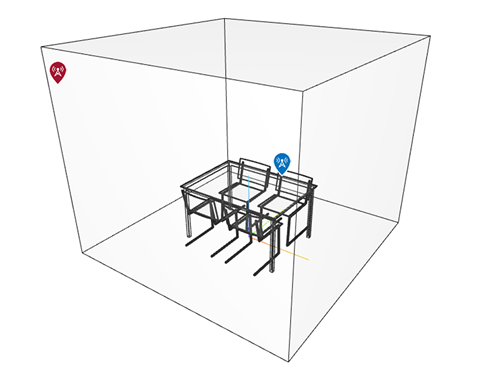

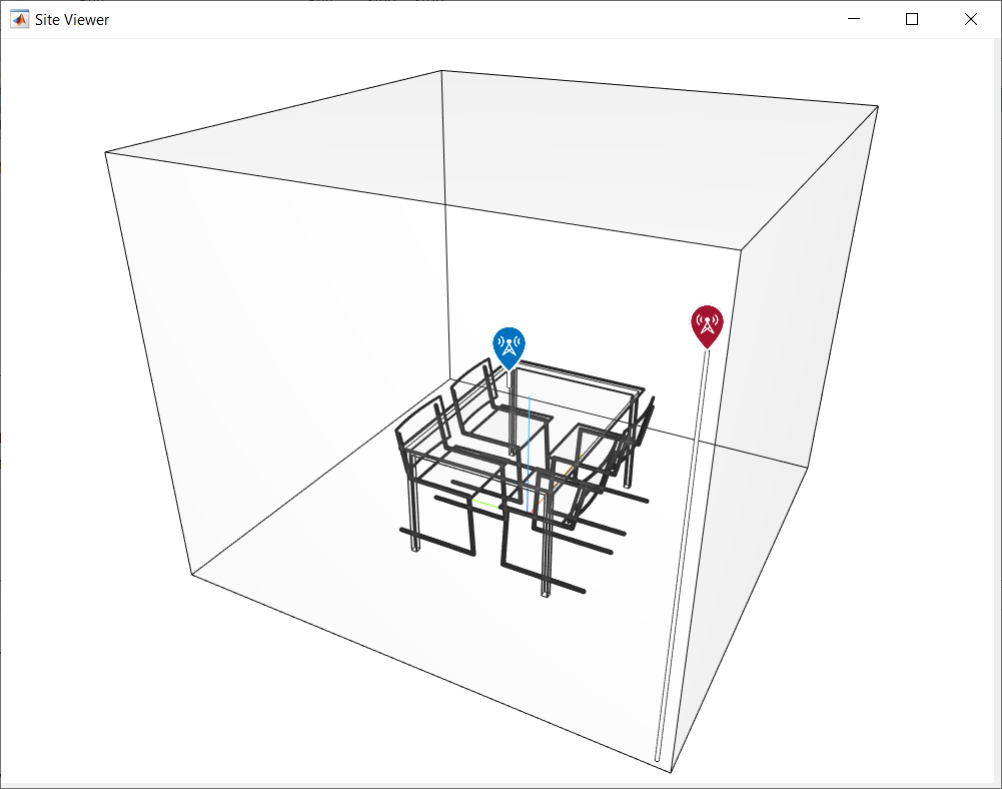

## Ray Tracing

Perform ray tracing analysis between the transmitter and receiver sites and return the [`comm.Ray`](docid:comm_ref#mw_09996ab4-973c-4434-a358-8d8189359c1a) objects, using the shooting and bouncing rays (SBR) method. Specify the surface material of the scene as wood and search for rays with up to 2 reflections. The SBR method supports up to 10 order of reflections. 

pm = propagationModel("raytracing", ...
    "CoordinateSystem","cartesian", ...
    "Method","sbr", ...
    "AngularSeparation","low", ...
    "MaxNumReflections",5, ...
    "BuildingsMaterial","concrete", ...
    "SurfaceMaterial","concrete");

rays = raytrace(tx,rx,pm);

Extract the computed rays from the cell array return.

rays = rays{1,1};

Examine the ray tracing results by looking at the number of reflections, propagation distance and path loss value of each ray. There are 25 rays found (one line-of-sight ray, 6 rays with one reflection, and 18 rays with two reflections).

[rays.NumInteractions]
[rays.PropagationDistance]
[rays.PathLoss]

Use the `plot` function to plot the rays in the 3-D scene in Site Viewer. Each ray is colored based on its path loss value. Click on a ray to view information about that ray.

plot(rays,"Colormap",jet,"ColorLimits",[50, 95])